# Evaluating power consumption

Copyright (C) 2022 Miodrag Bolic

 This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

We would like to acknowledge:  

[1] G. Dekkers, F. Rosas, S. Lauwereins, S. Rajendran, S. Pollin, B. Vanrumste, T. van Waterschoot, M. Verhelst and Peter Karsmakers, �A multi-layered energy consumption model for smart wireless acoustic sensor networks,� KU Leuven, Tech. Rep., December 2018. for providing the Matlab code. All the equations are from their paper.      

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter4/PowerEstimation'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Introduction

## A/D Converter

% From paper [1]
T=1;
channels=1;
Nadc= 12 ;%                       # ADC resolution [bit]
fs=10000;
Ts=1/fs;
FOM= 100*1e-13*10^3;       %    # [mJ/conv]
% ADC consumption
Padc = 2^Nadc * fs * FOM     % [mW] - eq. 10

Padc = 0.4096

Eadc = T*Padc*channels;       % [mJ] = [s]*[mW] - eq. 9

% Based on the data sheet for sigma delta ADS1114 from TI
i_oper=0.15;                 % [mA]
i_power_down=1e-3;           % [mA]
conversion_time=1/1000;      % [s]
Vdd=3;                       % [V]
Eadc=Vdd*(i_oper*conversion_time+i_power_down*(Ts-conversion_time));
Padc=Eadc/Ts                 % 

Padc = 4.4730


% Based on the data sheet for sucessive approximation AD7684 from Analog Devices
i_oper=0.56;                 % [mA]
i_power_down=1e-6;           % [mA]
conversion_time=10e-6;      % [s]
Vdd=3;                       % [V]
Eadc=Vdd*(i_oper*conversion_time+i_power_down*(Ts-conversion_time));
Padc=Eadc/Ts   

Padc = 0.1680

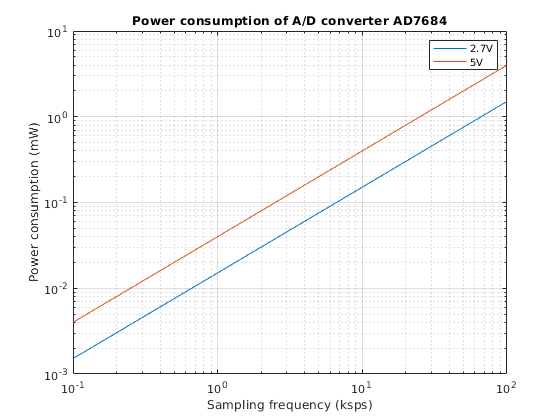


% Ploting power over sampling rates and Vdd
Vdd1=[2.7, 5];
i=1:1000;
fs1=100*i;
Ts1=1./fs1;
i_oper1=[0.56, 0.8];;  
Padc1(1,:)=Vdd1(1)*(i_oper1(1)*conversion_time+i_power_down*(Ts1-conversion_time))./Ts1;
Padc1(2,:)=Vdd1(2)*(i_oper1(2)*conversion_time+i_power_down*(Ts1-conversion_time))./Ts1;
loglog(fs1/1000,Padc1)
title('Power consumption of A/D converter AD7684')
xlabel('Sampling frequency (ksps)')
ylabel('Power consumption (mW)')
grid on
legend(['2.7V'], ['5V'])
annonation_save('',"Fig4.20.jpg", SAVE_FLAG);